Clases Series de Tiempo

Semana 04: 12 - 09 - 2025

Gráficos II

close all
clear all

% Leer los datos en formato Matlab

load data\datos_mareas_tortel_2020.mat
disp(datos_marea)

   1.0e+05 *

    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000

Grafico Inicial 

% Se nombra las columnas que existen dentro del archivo

time = datos_marea(:,1)

time = 1.0e+05 *

    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633


marea = datos_marea(:,2)

marea =     0.9859
    1.1653
    1.3572
    1.5192
    1.6249
    1.6469
    1.5630
    1.3908
    1.1916
    1.0088
    0.8431
    0.7165
    0.6883
    0.7742
    0.9198


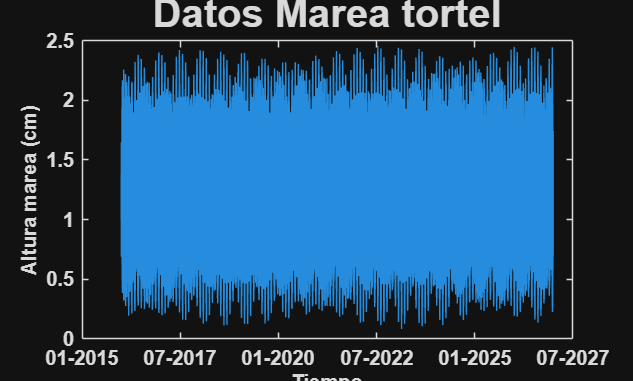


% Plot del grafico de los datos de marea de time

plot(time,marea)
title("Datos Marea tortel",FontSize =20)
xlabel("Tiempo", FontSize = 10)
ylabel("Altura marea (cm)", FontSize = 10)
set(gca,'FontWeight',"bold")
datetick('x','mm-yyyy') % Función para gráficar eje x como tiempo

Guardar datos de una sola sección 

ini = (4*365*24)+(7*28-3);
fin = ini+367+24;

time_2020 = time(ini:fin);
marea_2020 = marea(ini:fin);
save datos_mareas_tortel_nuevo.mat time_2020 marea_2020

Gráfico altura marea 2020

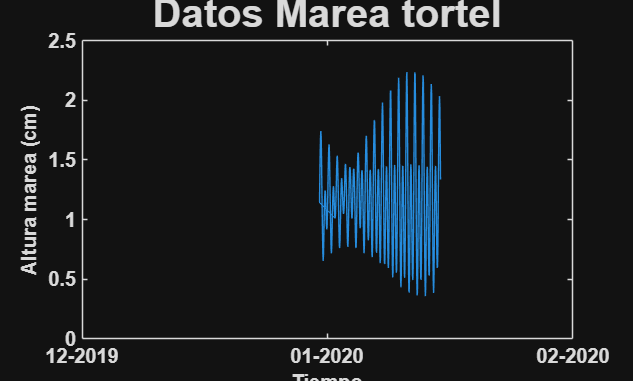

plot(time_2020,marea_2020)
title("Datos Marea tortel",FontSize =20)
xlabel("Tiempo", FontSize = 10)
ylabel("Altura marea (cm)", FontSize = 10)
set(gca,'FontWeight',"bold")
datetick('x','mm-yyyy') % Función para gráficar eje x como tiempo

Datos del Pacifíco

% Datos del niño NOAA
enso = load ('data/data_nino.txt');

Gráfico de datos NOAA

% Análisis de datos de NOAA

YR = enso(:,1);
MO = enso(:,2);
en12 = enso(:,3);
en34 = enso(:,9);

n = length(YR);
DY = ones (n,1);

% Matriz para unir año y mes

Fecha = datenum([YR, MO, DY])

Fecha =       723912
      723943
      723971
      724002
      724032
      724063
      724093
      724124
      724155
      724185
      724216
      724246
      724277
      724308
      724336


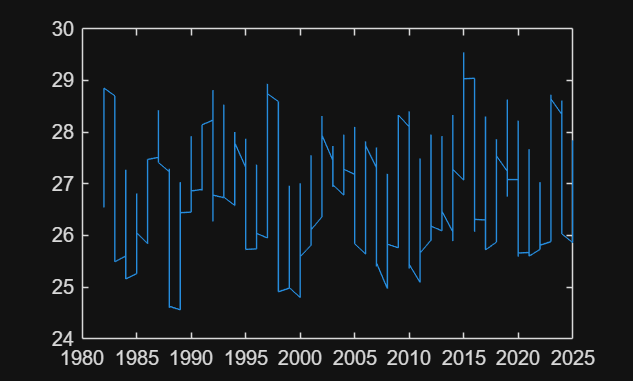


% Plot datos Niño1+2 y Niño 3.4

subplot
plot(YR, en34)

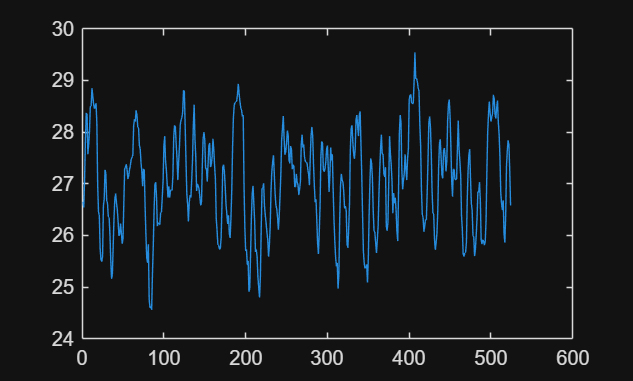

subplot
plot(en34)

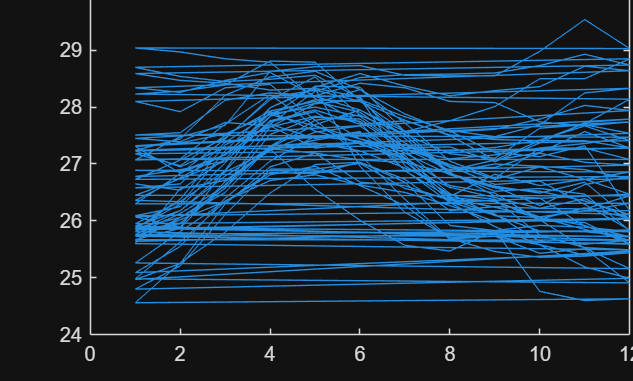

subplot
plot(MO,en34)

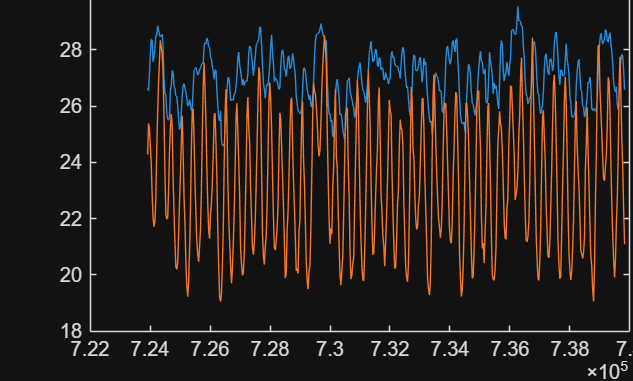


% Figura final 
plot(Fecha,en34, Fecha,en12)

title("Enso (niño 1+2 y niño 3.4)",FontSize =20)
xlabel("Tiempo", FontSize = 10)
ylabel("SST (c)", FontSize = 10)
legend("El niño 3.4","El niño 1 + 2")
set(gca,'FontWeight',"bold")
datetick('x','mm-yyyy')